# EX. 3. 

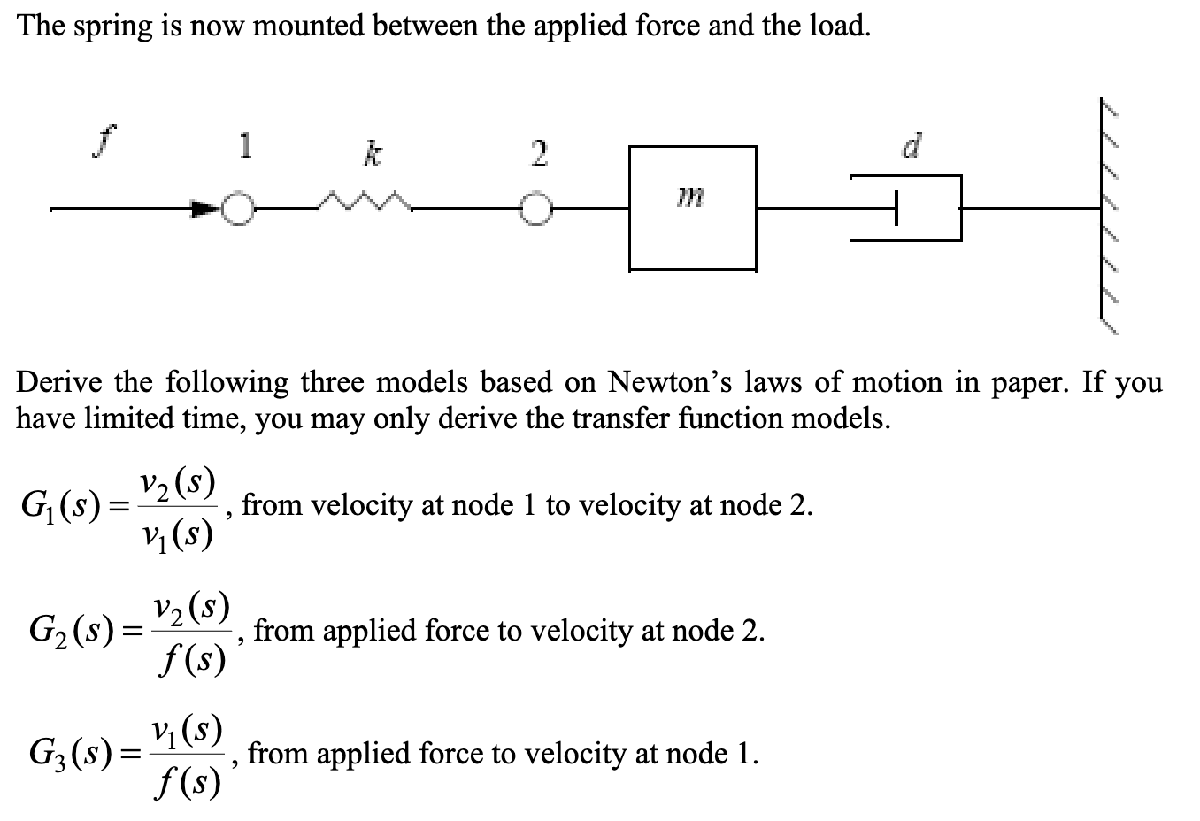

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m
k = 8; % N/m


### Transfer function models

The transfer functions were derived on paper according to the following: 


$$G_1(s) = \frac{k}{ms^2 +ds + k}
$$



$$G_2(s) = \frac{1}{ms + d}
$$



$$G_3(s) = \frac{ms^2 + ds + k}{k(ms + d)}
$$


% Derived transfer function model from velocity at node 1 to velocity at
% node 2

s = tf('s');

G1 = k / (m*s^2 + d*s + k);

% Derived transfer function model from force to velocity at node 2
G2 = 1 / (m*s + d);

% Derived transfer function model from force to velocity at node 1
G3 = (m*s^2 + d*s + k) / (k*(m*s + d));

% send to kaiget@kth.se for help


### Step response from velocity at node 1 to velocity at node 2

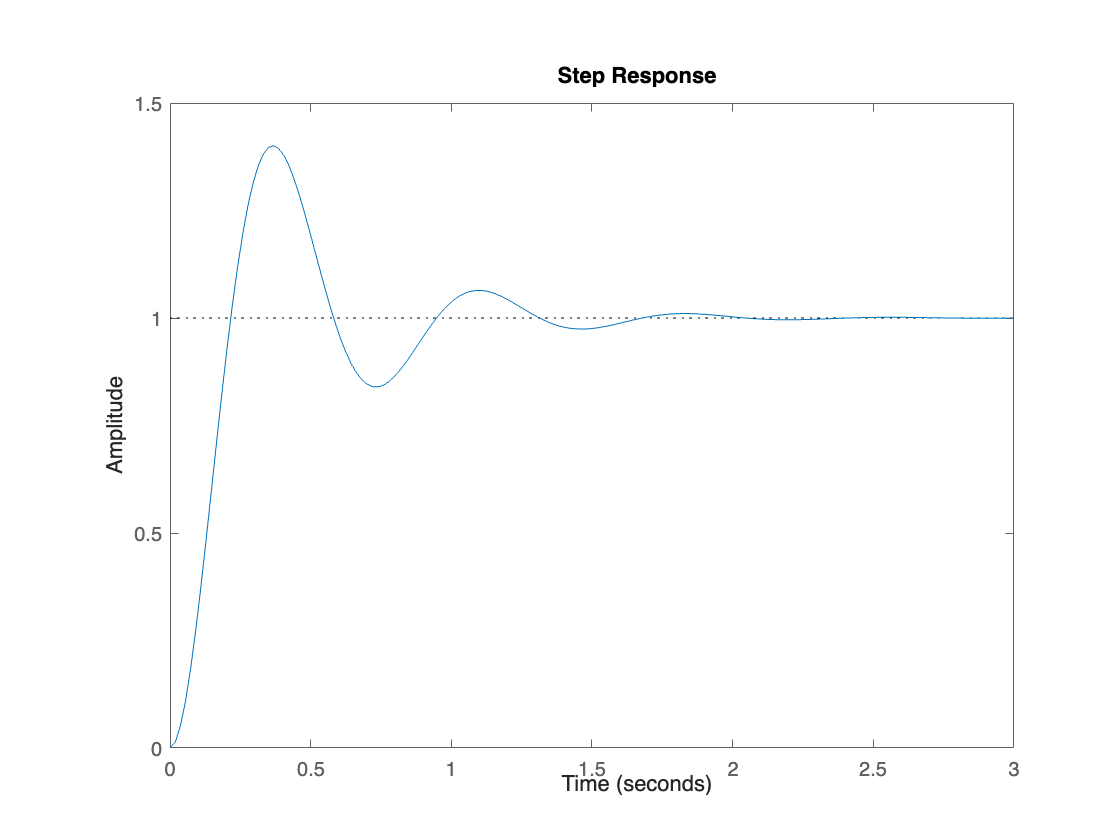

sp1 = stepplot(G1);

### Step response from force to velocity at node 2

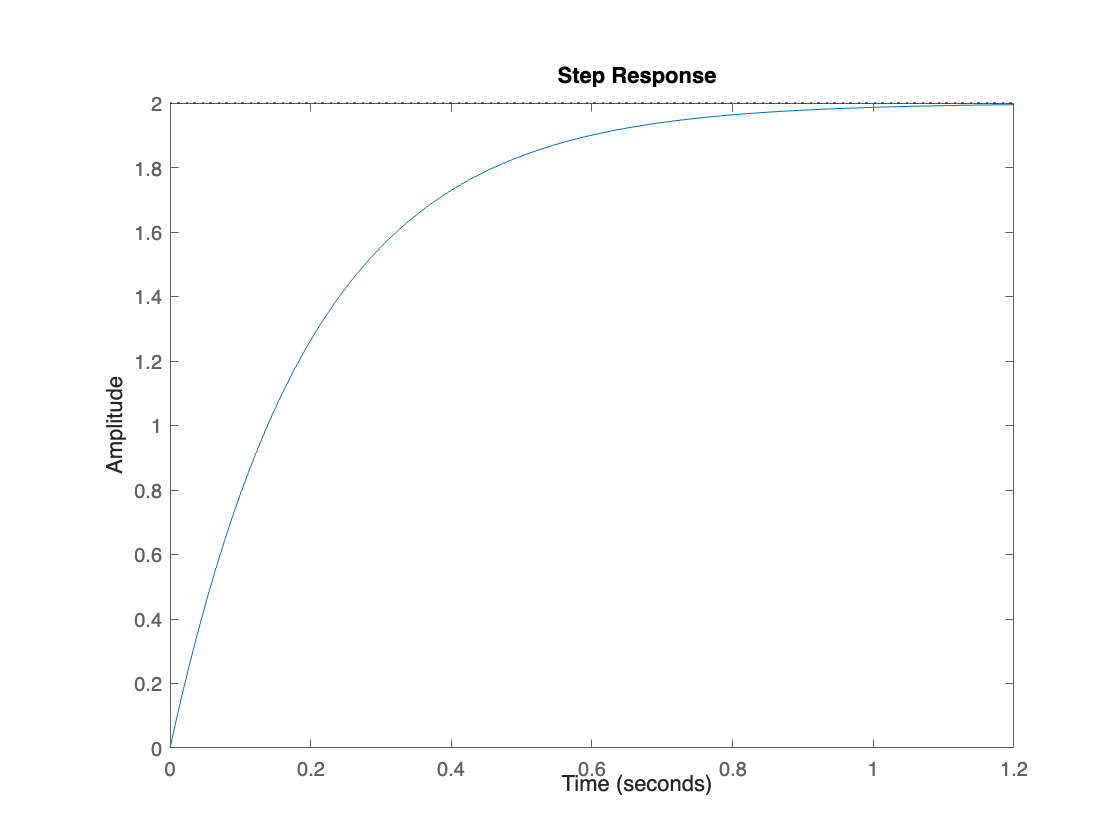

sp2 = stepplot(G2);

### Step response from force to velocity at node 1

G3 is an improper transfer function as the order of the numerator is higher than the order of the denominator

### Simulink and simscape models

#### Step response of simulink transfer function and simscape model from force to velocity at node 2 with step input

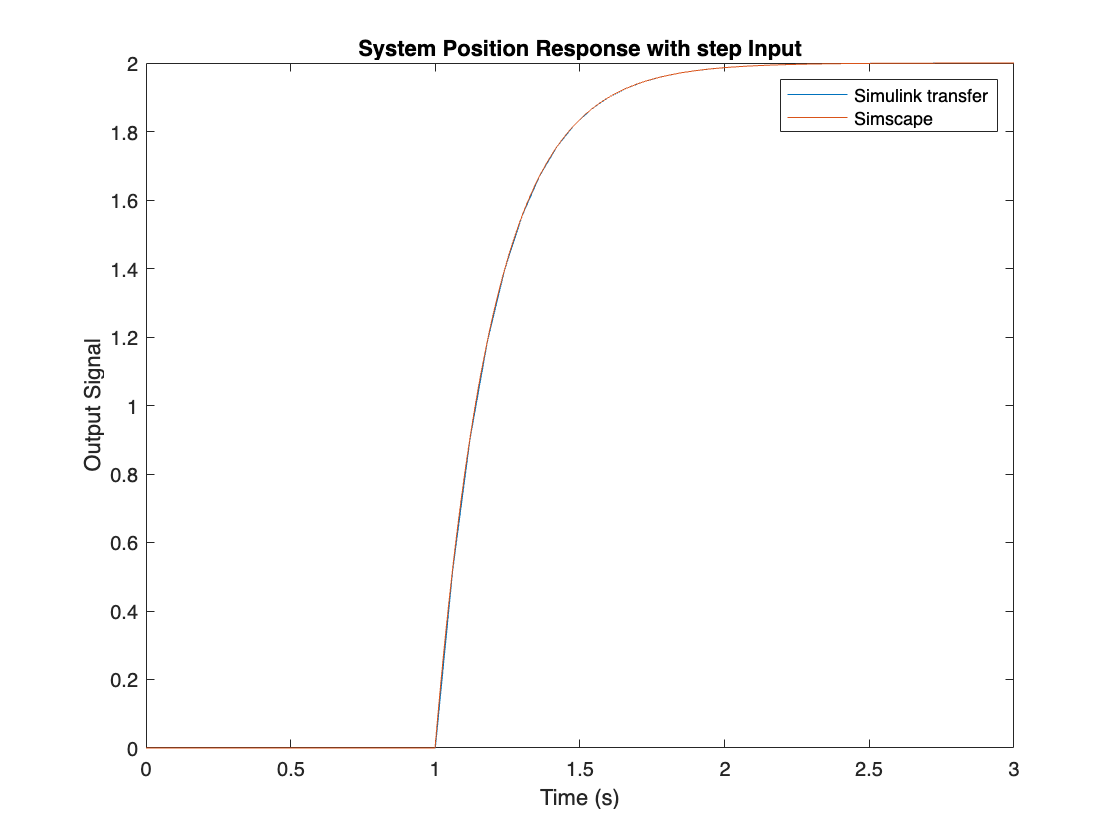

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 2 Sim 2,3 Ex.3').Values.Data; 


model_name = 'excercise1_3tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('velocity').Values.Data; 


figure;
plot(sim_time22, output_signal22);
title(['System Velocity Response from force to v2 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
legend("Simulink transfer", "Simscape")
hold off

Plots for step response of the system from force to velocity at node 2 simulated using both simulink and simscape shown to give the same result. Note that a 1s delay was added to the step input to correctly show system behavior of G3 in simscape. This is not part of the system response in this case and the plot can be assumed to start at 0 instead of 1. 

#### Step response of simulink transfer function and simscape model from velocity at node 1 to velocity at node 2 with step input

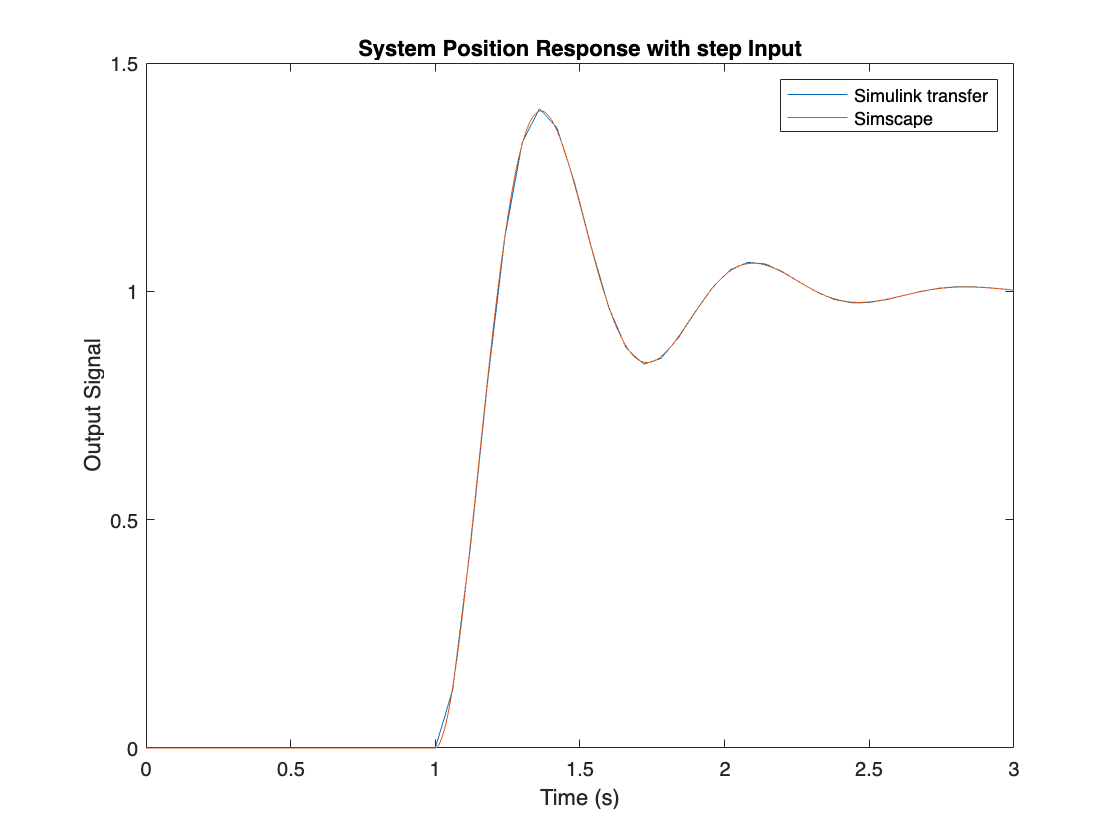

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 2 Sim 1 Ex.3').Values.Data; 


model_name = 'excercise1_3tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('velocity').Values.Data; 


figure;
plot(sim_time22, output_signal22);
title(['System Velocity Response from v1 to v2 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
legend("Simulink transfer", "Simscape")
hold off

Plots for step response of the system from velocity at node 1 to velocity at node 2 simulated using both simulink and simscape shown to give the same result. Note that a 1s delay was added to the step input to correctly show system behavior of G3 in simscape. This is not part of the system response in this case and the plot can be assumed to start at 0 instead of 1. 

#### Step response of simulink transfer function and simscape model from force to velocity at node 1 with step input

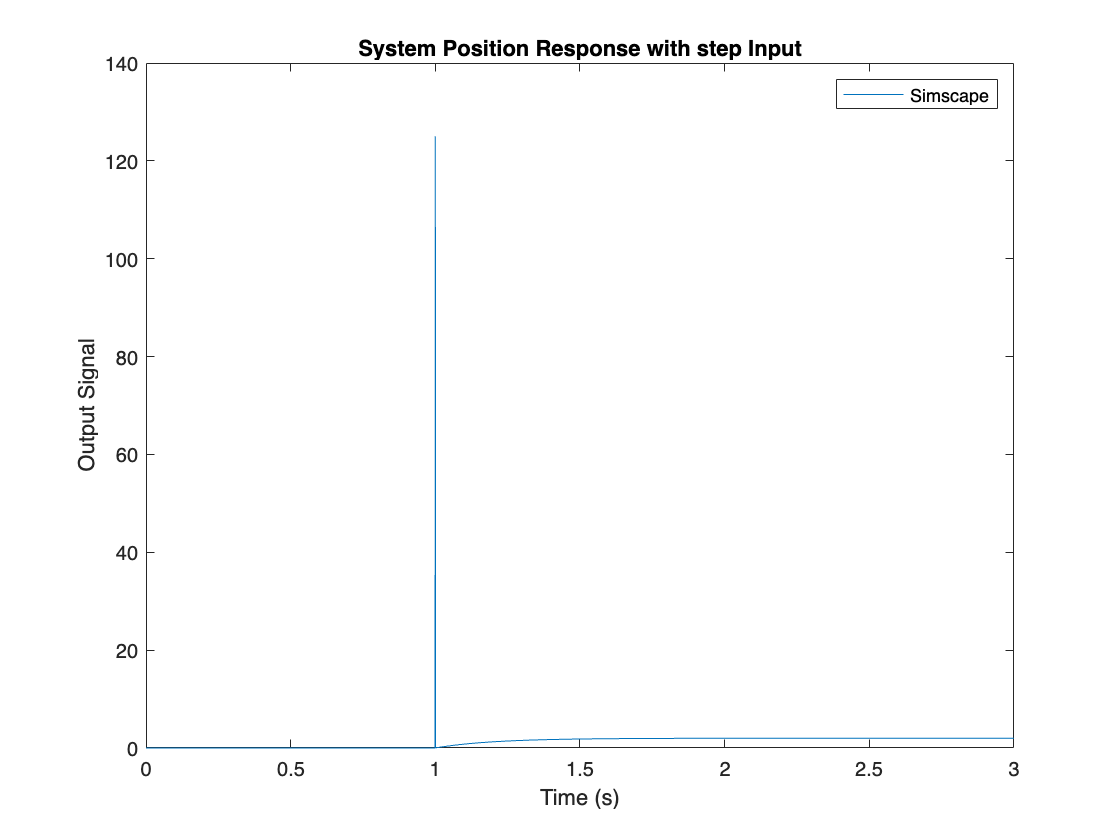

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 1 Sim 2,3 Ex.3').Values.Data; 


figure;

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
legend("Simscape")

title(['System Velocity Response from force to v1 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

In this graph, which could only be simulated in simscape as both the matlab step response function and the simulink transfer function block gave errors, it is possible to see the effect of tryin to measure the velocity at a massless point. There is an infinite acceleration at point 1 when a force is applied to it. The transfer function is an improper system which also illustrates how this system is technically physically impossible since no massless points can exist. 